`Erfan Panahi   810198369`

## Communication Systems I

# Computer Assignement 1

# ` Part 1.`

`Fourier transform of "data.wav":`

- `Amplitude:`

[data,fs_data]=audioread('data.wav');
ft_data=fftshift(fft(data));
fr_data=-fs_data/2:fs_data/length(data):(fs_data-1)/2;
plot(fr_data,abs(ft_data)/length(data));

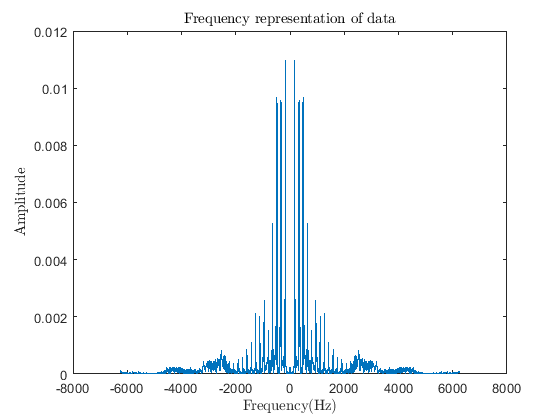

title('Frequency representation of data','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Amplitude','Interpreter','latex');

- `Phase:`

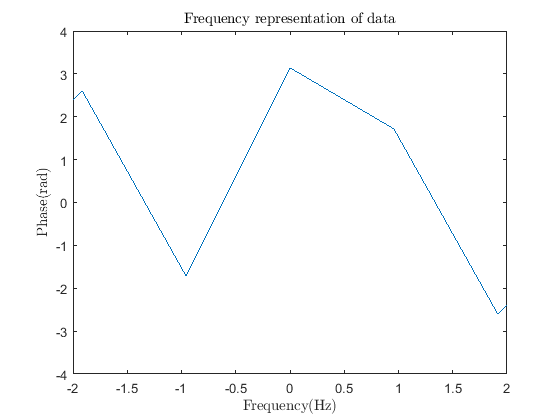

plot(fr_data,angle(ft_data));
axis([-2 2 -4 4]);
title('Frequency representation of data','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('Phase(rad)','Interpreter','latex');

# `Part 2.`

`Importing output signal "y.wav":`

[y,fs_y]=audioread('y.wav');
y=y(:,1);
fs_y

fs_y = 44100

# `Part 3.`

`Calculating `$\alpha ,\beta ,k_1 ,k_2$ `:`

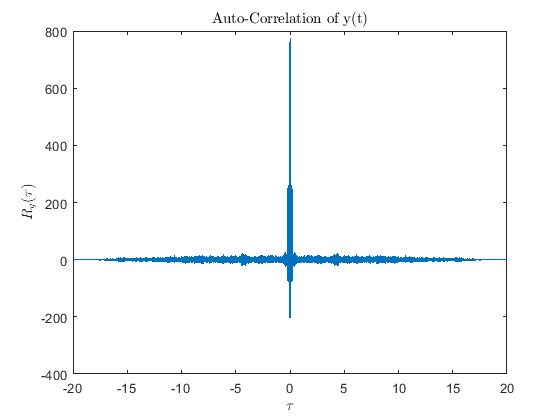

R_y=xcorr(y);
tau=-(length(y)-1)/fs_y:1/fs_y:(length(y)-1)/fs_y;
plot(tau,R_y);
title('Auto-Correlation of y(t)','Interpreter','latex');
xlabel('$ \tau $','Interpreter','latex');
ylabel('$R_y(\tau)$','Interpreter','latex');

using xlim to see the maximum of correlation better:

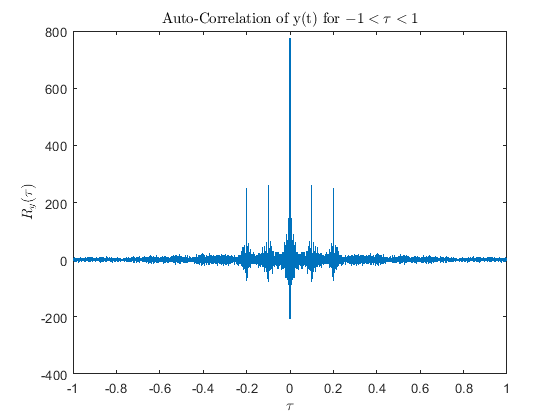

plot(tau,R_y);
xlim([-1,1]);
title('Auto-Correlation of y(t) for $ -1<\tau<1 $','Interpreter','latex');
xlabel('$ \tau $','Interpreter','latex');
ylabel('$R_y(\tau)$','Interpreter','latex');

using axis to see the maximum of correlation better:

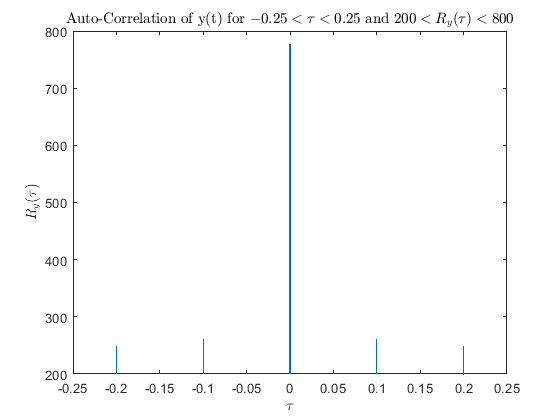

plot(tau,R_y);
axis([-0.25 0.25 200 800])
title('Auto-Correlation of y(t) for $ -0.25<\tau<0.25 $ and $ 200<R_y(\tau)<800 $','Interpreter','latex');
xlabel('$ \tau $','Interpreter','latex');
ylabel('$R_y(\tau)$','Interpreter','latex');

# ` Part 4.`

`Calculating frequency respons: `$H\left(f\right)$


$$y{\left(t\right)}=x{\left(t\right)}+0.3x{\left(t-0.1\right)}+0.4x{\left(t-0.2\right)}$$



$$x\left(t\right)=\delta \left(t\right)$$

$$\Rightarrow h{\left(t\right)}=\delta {\left(t\right)}+0.3\delta {\left(t-0.1\right)}+0.4\delta {\left(t-0.2\right)}$$



$$\to^{f\ldotp t} H{\left(f\right)}=1+0.3e^{-0.2\pi f} +0.4e^{-0.4\pi f}$$


# ` Part 5.`

`Calculating impulse respons: `$h\left(t\right)$

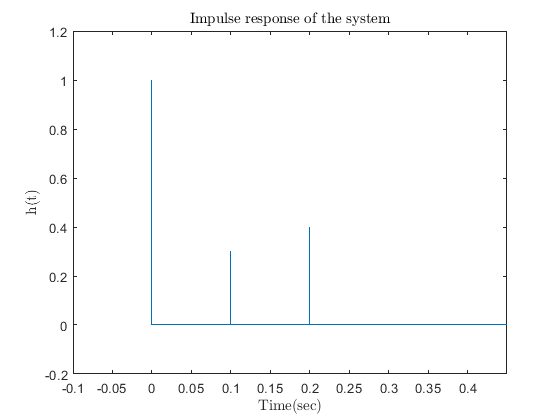

f=-fs_y/2:fs_y/length(y):fs_y/2;
t=0:1/fs_y:(length(y)-1)/fs_y;
H_f=1+0.3*exp(-0.2*1i*pi*f)+0.4*exp(-0.4*1i*pi*f);
h_t=ifft(H_f,length(y));
plot(t,real(h_t));
axis([-0.1 0.45 -0.2 1.2]);
title('Impulse response of the system','Interpreter','latex');
xlabel('Time(sec)','Interpreter','latex');
ylabel('h(t)','Interpreter','latex');

# ` Part 6.`

`Calculating input signal: `$x\left(t\right)$

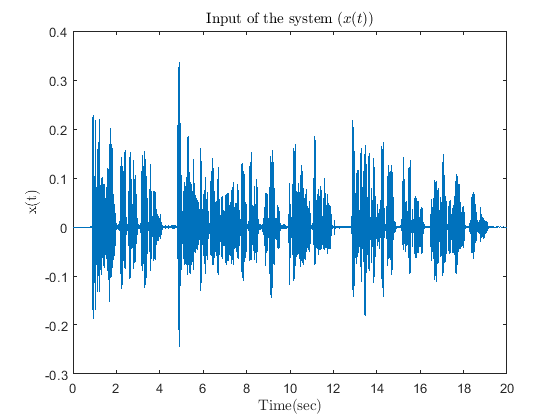

x=filter(1,real(h_t(1:0.2*fs_y+1)),y);
plot(t,x);
title('Input of the system ($x(t)$)','Interpreter','latex');
xlabel('Time(sec)','Interpreter','latex');
ylabel('x(t)','Interpreter','latex');

# ` Part 7.`

`Calculating output signal with 'conv': `$z\left(t\right)=x\left(t\right)*h\left(t\right)$

sound(real(x),fs_y);
audiowrite('x.wav',real(x),fs_y);

# ` Part 8.`

`Calculating output using `$z\left(t\right)=x\left(t\right)*h\left(t\right)$ `:`

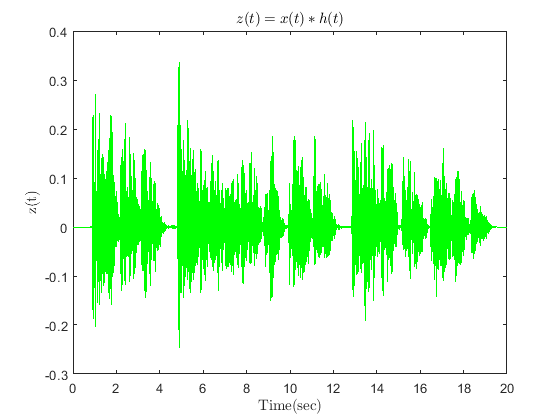

z = conv(real(x),real(h_t(1:0.2*fs_y+1)));
z=z(1:length(y));
plot(t,z,'g');
xlim([0 20]);
title('$z(t)=x(t)*h(t)$','Interpreter','latex');
xlabel('Time(sec)','Interpreter','latex');
ylabel('z(t)','Interpreter','latex');

`Calculated output `$y\left(t\right)$ `:`

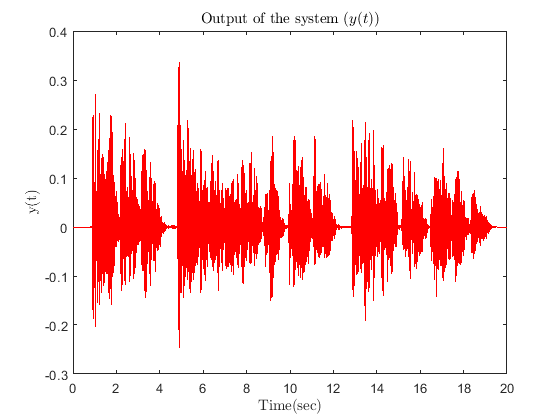

plot(t,y,'r');
title('Output of the system ($y(t)$)','Interpreter','latex');
xlabel('Time(sec)','Interpreter','latex');
ylabel('y(t)','Interpreter','latex');

`Comparing `$y\left(t\right)$` and `$z\left(t\right)$ `:`

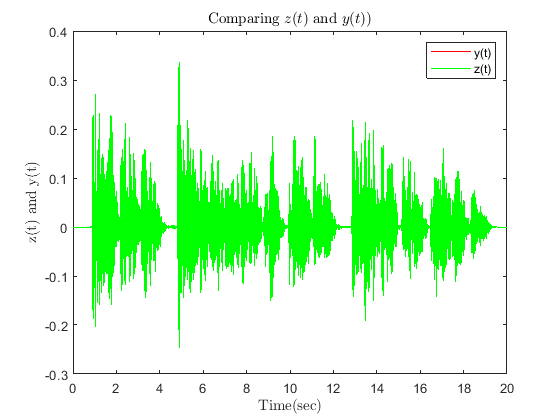

plot(t,y,'r',t,z,'g');
legend('y(t)','z(t)');
title('Comparing $z(t)$ and $y(t)$)','Interpreter','latex');
xlabel('Time(sec)','Interpreter','latex');
ylabel('z(t) and y(t)','Interpreter','latex');

`Comparing `$y\left(t\right)$` and `$z\left(t\right)$ `using ``immse``:`

immse(y,z)

ans = 2.7849e-37

# ` Part 9.`

`Creating echoes:`

`To have two echoes the impulse response is defined as follows:`


$$h\left(t\right)=\delta \left(t\right)+0\ldotp 5\delta \left(t-0\ldotp 2\right)+0\ldotp 2\delta \left(t-0\ldotp 4\right)$$


`So `$y\left(t\right)=x\left(t\right)+0\ldotp 5x\left(t-0\ldotp 2\right)+0\ldotp 2x\left(t-0\ldotp 4\right)$

clear;
[P9_input,fs_P9]=audioread('P9_input.wav');
h9_t=1;
h9_t(0.2*fs_P9)=0.5;
h9_t(0.4*fs_P9)=0.2;
P9_output=conv(P9_input,h9_t);
sound(P9_output,fs_P9);
audiowrite('my_voice.wav',P9_output,fs_P9);

# ` Part 10.`

`define and calculate input `$x\left(t\right)$` ,impulse response `$h\left(t\right)$` and output `$y\left(t\right)$` :`

clear;
%input
[x,fs]=audioread('x.wav');
tau=-(length(x)-1)/fs:1/fs:(length(x)-1)/fs;
f=-fs+fs/length(x):fs/length(x):fs-fs/length(x);
%impulse response
h_t=1;
h_t(0.2*fs)=0.5;
%output
y=conv(x,h_t);
y=y(1:length(x));

`Calculate the auto-correlations (`$R_x \left(\tau \right)$ , $R_y \left(\tau \right)$`) and density of input (`$G_x \left(f\right)$`) and `$|H\left(f\right)|^2$`:`

%auto-correlations
Ry=xcorr(y);
Rx=xcorr(x);
%Spectural density of input
Gx=fftshift(fft(Rx))/length(Rx);

`left-side of part a:`


$${\mathit{\mathbf{R}}}_{\mathit{\mathbf{y}}\mathit{\mathbf{x}}} \left(\tau \right)=\mathit{\mathbf{x}}\mathit{\mathbf{c}}\mathit{\mathbf{o}}\mathit{\mathbf{r}}\mathit{\mathbf{r}}{\left(\mathit{\mathbf{x}}{\left(\mathit{\mathbf{t}}\right)},\mathit{\mathbf{y}}\left(\mathit{\mathbf{t}}\right)\right)}$$


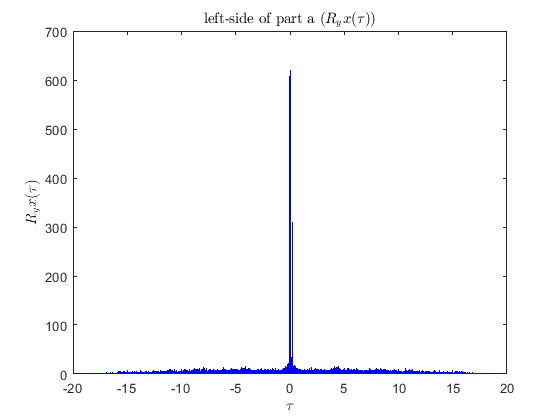

Ryx=xcorr(y,x);
plot(tau,abs(Ryx),'b');
title('left-side of part a ($R_yx(\tau)$)','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('$R_yx(\tau)$','Interpreter','latex');

`right-side of part a:`


$${\mathit{\mathbf{R}}}_{\mathit{\mathbf{y}}\mathit{\mathbf{x}}} {\left(\tau \right)}={\mathit{\mathbf{R}}}_{\mathit{\mathbf{x}}} {\left(\tau \right)}\mathit{\mathbf{*}}\;\mathit{\mathbf{h}}\left(\tau \right)$$


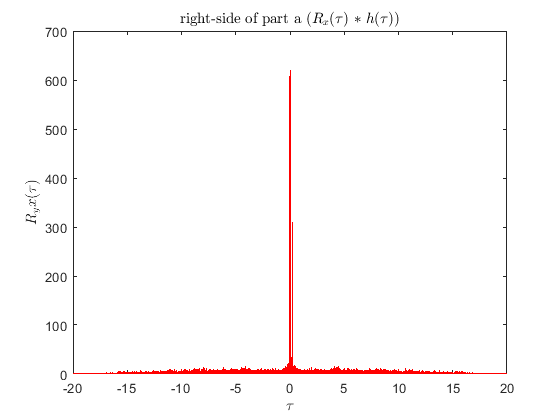

RRyx=conv(Rx,h_t);
RRyx=RRyx(1:length(Rx));
plot(tau,abs(RRyx),'r');
title('right-side of part a ($R_x(\tau)$ $*$ $h(\tau)$)','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('$R_yx(\tau)$','Interpreter','latex');

`Comparing left-side and right-side of part a:`

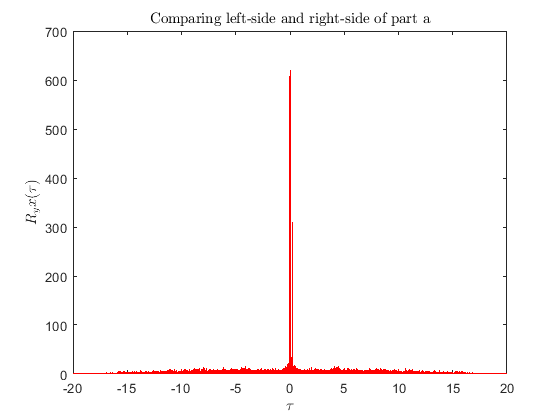

plot(tau,abs(Ryx),'b',tau,abs(RRyx),'r');
title('Comparing left-side and right-side of part a','Interpreter','latex');
xlabel('$\tau$','Interpreter','latex');
ylabel('$R_yx(\tau)$','Interpreter','latex');

`Mean squared error of Part a:`

mse_part_a=immse(RRyx,Ryx)

mse_part_a = 1.9137e-09

`left-side of part b:`


$${\mathit{\mathbf{G}}}_{\mathit{\mathbf{y}}} \left(\mathit{\mathbf{f}}\right)=\mathcal{F}{\left\{{\mathit{\mathbf{R}}}_{\mathit{\mathbf{y}}} {\left(\tau \right)}\right\}}$$


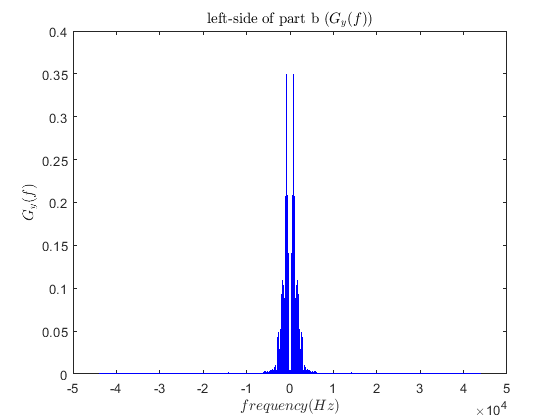

Gy=fftshift(fft(Ry))/length(Ry);
plot(f,abs(Gy),'b');
title('left-side of part b ($G_y(f)$)','Interpreter','latex');
xlabel('$frequency(Hz)$','Interpreter','latex');
ylabel('$G_y(f)$','Interpreter','latex');

`right-side of part b:`


$${\mathit{\mathbf{G}}}_{\mathit{\mathbf{y}}} {\left(\mathit{\mathbf{f}}\right)}={\mathit{\mathbf{G}}}_{\mathit{\mathbf{x}}} {\left(\mathit{\mathbf{f}}\right)}\ldotp {{\left|\mathit{\mathbf{H}}{\left(\mathit{\mathbf{f}}\right)}\right|}}^2$$


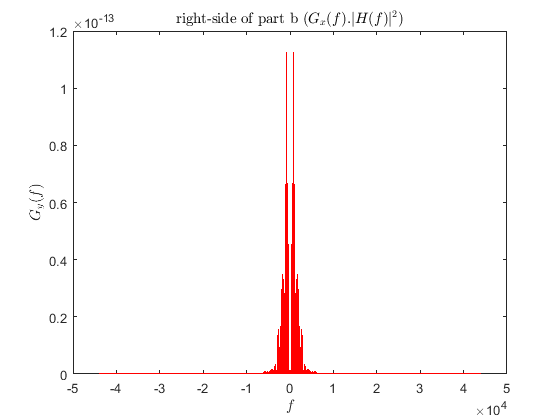

h_t(length(tau))=0;
H_f=fftshift(fft(h_t))/length(h_t);
absH2f=abs(H_f).^2;
GGy=real(Gx).*transpose(absH2f);
plot(f,abs(GGy),'r');
title('right-side of part b ($G_x(f)$.$|H(f)|^2$)','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$G_y(f)$','Interpreter','latex');

`Comparing left-side and right-side of part b:`

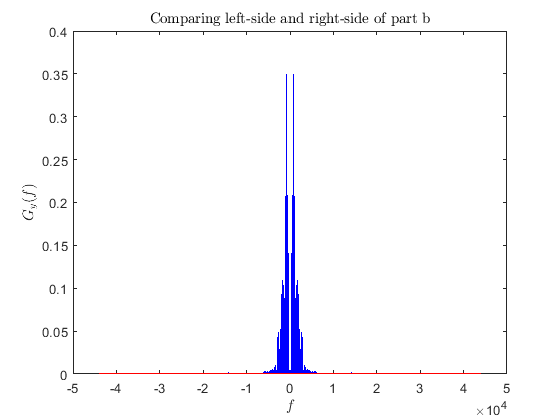

plot(f,abs(Gy),'b',f,abs(GGy),'r');
title('Comparing left-side and right-side of part b','Interpreter','latex');
xlabel('$f$','Interpreter','latex');
ylabel('$G_y(f)$','Interpreter','latex');

`Mean squared error of Part b:`

mse_part_b=immse(GGy,Gy)

mse_part_b = 1.2578e-05